[nc, fs] = audioread('audio_experiments/mics_nc.wav');
[foam, fs] = audioread('audio_experiments/mics_foam.wav');

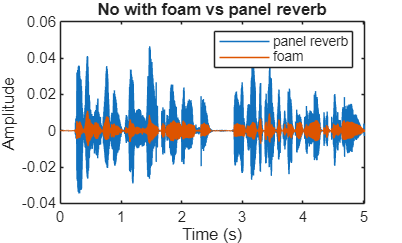

t = (0:length(foam(:, 1)) - 1) / fs;

figure
plot(t, nc(:, 1))
hold on
plot(t, foam(:, 1))
legend('panel reverb', 'foam')
title('No with foam vs panel reverb')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([t(1), t(end)])

target = nc(:, 1);
ref = nc(:, 2);

cutoff = 400;
target = highpass(target, cutoff, fs);
ref = highpass(ref, cutoff, fs);

source_to_ref = 2;
ir_len = 128;
filter_order = 2 * ir_len;
step_size = 0.9;

panel_ir = clipped_irs(ir_len, source_to_ref);
panel_ir = highpass(panel_ir, cutoff, fs);

fxlms = FxLMS(ref, target, panel_ir, filter_order, step_size, true);
[pred, mses] = fxlms.learn(25);

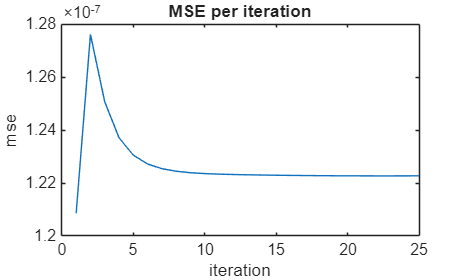

figure
plot(mses)
title('MSE per iteration')
xlabel('iteration')
ylabel('mse')

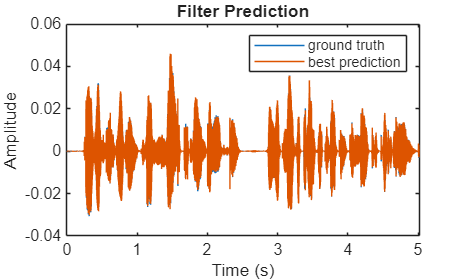

t = (0:length(target) - 1) / fs;
figure
plot(t, target)
hold on
plot(t, pred);
legend("ground truth", "best prediction")

title("Filter Prediction")
xlabel("Time (s)")
ylabel("Amplitude")
xlim([t(1), t(end)]);

hold off

save_cancel_clip(-fxlms.ref_filt, 'fxlms_same_session');

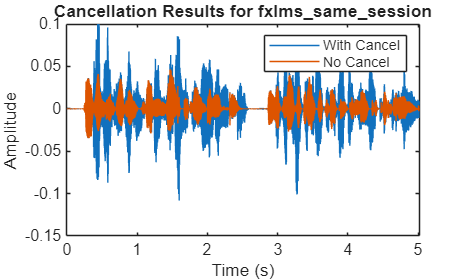

c = CancelAnalysis('fxlms_same_session');
c.plot_cancel_results();

save_cancel_clip(fxlms.ref_filt, 'fxlms_same_session');

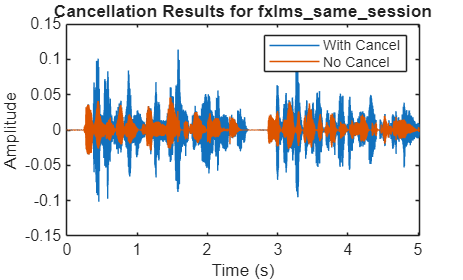

c = CancelAnalysis('fxlms_same_session');
c.plot_cancel_results();